# Inspired by Choi Iteration 00

clear

## Definitions

### Plunger

pl_d_out   =	25.5;	% mm
pl_d_hole  =	1.5;    % mm
pl_height  =	15;	    % mm
pl_d_in    =	15.5;	% mm
pl_A_out   =    pl_d_out^2/4*pi;    % mm^2
pl_A_hole  =    pl_d_hole^2/4*pi    % mm^2

pl_A_hole = 1.7671

pl_A_in    =    pl_d_in^2/4*pi;    % mm^2
pl_A_u     =    pl_A_out - pl_A_in;     % mm^2
pl_m       =    0.012;  % kg
pl_rom     =    0.003;  % m

### Outlet

o_d_out	=   25.51;	    % mm
o_d_in	=   13.035;	% mm
A_adj = o_d_out^2/4*pi - pl_A_out % mm^2

A_adj = 0.4006

### Pintle Groove

pg_d	    =   13.035;	% mm
PG_depth	=   30.2;	% mm

### Pintle

pi_height	=   29.4;	% mm
pi_d_out	=   12.84;	% mm
pi_d_in	    =   16.022;	% mm

### Volume

v_closed	=   2339.808;	% mm^3
v_open	    =   812.994;	% mm^3

## Test Case 1

- Infinite Upstream Volume @ 400 bar 273 K

- Infinite Downstream Volume @ 1 bar 273 K

- Pilot closed @ t(0)

- P_cr = 400 bar @ t(0)

- Plunger displacement x = 0 @ t(0)

dt = 0.000001; % s
gam = 1.4;
R = 296.8; % J/kgK

damper = 500; % kg/s

t(1) = 0; % s
P_cr(1) = 400; % bar
T_cr(1) = 273; % K
P_u(1) = 400; % bar
T_u(1) = 273; % K
P_d(1) = 1; % bar
T_d(1) = 273; % K
x(1) = 0; % m
v(1) = 0; % m/s
a(1) = 0; % m/s^2
V_cr(1) = v_closed; % mm^3
pilot(1) = 0; % 1 = open, 0 = closed
A_m(1) = o_d_in * pi * x(1) * 10^-3; % mm^2
m_dot_u_cr(1) = 0; % kg/s
m_dot_cr_d(1) = 0; % kg/s
m_dot_u_d(1) = 0; % kg/s
m_dot_cr_net(1) = 0; % kg/s
F_cr(1) = B_to_Pa(P_cr(1)) * pl_A_out * 10^-6; % N
F_d(1) = B_to_Pa(P_d(1)) * pl_A_in * 10^-6; % N
F_u(1) = B_to_Pa(P_u(1)) * pl_A_u * 10^-6; % N
F_f(1) = - damper * v(1); % N
F(1) = - F_cr(1) + F_d(1) + F_u(1); % N

m_cr(1) = 0.014 * B_to_Pa(P_cr(1)) * v_closed * 10^-9 / (T_cr(1) * R);

for i = 2:0.01/dt
    t(i) = t(i-1) + dt; % s
    pilot(i) = i < 0.005/dt; % 1 = open, 0 = closed
    
    P_u(i) = P_u(i-1); % bar
    T_u(i) = T_u(i-1); % K
    P_d(i) = P_d(i-1); % bar
    T_d(i) = T_d(i-1); % K
    
    % Calculate forces
    F_cr(i) = B_to_Pa(P_cr(i-1)) * pl_A_out * 10^-6; % N
    F_d(i) = B_to_Pa(P_d(i-1)) * pl_A_in * 10^-6; % N
    F_u(i) = B_to_Pa(P_u(i-1)) * pl_A_u * 10^-6; % N
    F_f(i) = - damper * v(i-1); % N
    F(i) = - F_cr(i) + F_d(i) + F_u(i) + F_f(i); % N
    
    % Calculate displacement from previous forces
    x(i) = x(i-1) + v(i-1)*dt + 0.5*a(i-1)*dt^2; % m
    v(i) = v(i-1) + a(i-1)*dt; % m/s
    a(i) = F(i) / pl_m; % m/s^2
    if x(i) < 0
        x(i) = 0; % m
        v(i) = 0; % m/s
        a(i) = 0; % m/s^2
    elseif x(i) > 0.003
        x(i) = 0.003; % m
        v(i) = 0; % m/s
        a(i) = 0; % m/s^2
    end
    
    % Calculate Main area with new displacement
    A_m(i) = o_d_in * pi * x(i) * 10^-3; % m^2
    
    % Calculate Critical volume after displacement
    V_cr(i) = (pl_rom - x(i)) * (v_closed - v_open) / pl_rom + v_open; % mm^3
    
    % Isentropic Compression
    P_cr(i) = P_cr(i-1) * (V_cr(i-1)/V_cr(i))^gam; % Bar
    T_cr(i) = T_cr(i-1) * (P_cr(i)/P_cr(i-1))^(1-1/gam); % K
    
    m_dot_u_cr(i) = mdot_orifice(P_u(i-1),P_cr(i) ,gam,A_adj    *10^-6,T_u(i-1),R); % kg/s
    m_dot_cr_d(i) = mdot_orifice(P_cr(i), P_d(i-1),gam,pl_A_hole*10^-6,T_cr(i), R) * (pilot(i)==1); % kg/s
    m_dot_u_d(i) = mdot_orifice(P_u(i-1),P_d(i-1),gam,A_m(i),T_u(i-1),R); % kg/s
    
    m_dot_cr_net(i) = m_dot_u_cr(i) - m_dot_cr_d(i); % kg/s
    
    m_cr(i) = m_cr(i-1) + dt * m_dot_cr_net(i); % kg
    
    [P_cr(i), T_cr(i)] = tank_discharge_P(P_cr(i),T_cr(i),m_cr(i-1),...
         - m_dot_cr_net(i) * dt,gam); % bar, K
end


## Results

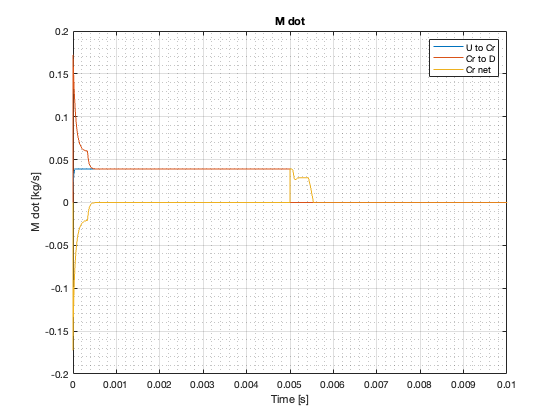

figure(1)
plot(t,m_dot_u_cr,t,m_dot_cr_d,t,m_dot_cr_net)
grid on, grid minor, xlabel('Time [s]'), ylabel('M dot [kg/s]'), title('M dot')
legend('U to Cr', 'Cr to D', 'Cr net')

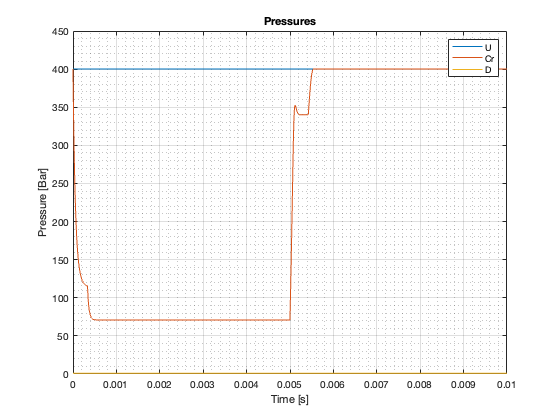

figure(2)
plot(t,P_u,t,P_cr,t,P_d)
grid on, grid minor, xlabel('Time [s]'), ylabel('Pressure [Bar]'), title('Pressures')
legend('U','Cr','D')

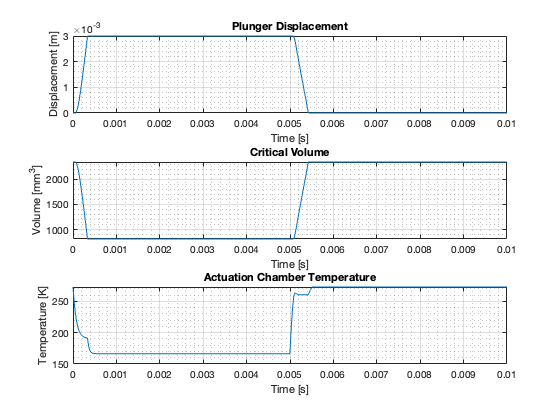

figure(3)
subplot(3,1,1)
plot(t,x)
grid on, grid minor, xlabel('Time [s]'), ylabel('Displacement [m]'), title('Plunger Displacement')
subplot(3,1,2)
plot(t,V_cr)
grid on, grid minor, xlabel('Time [s]'), ylabel('Volume [mm^3]'), title('Critical Volume')
subplot(3,1,3)
plot(t,v)
grid on, grid minor, xlabel('Time [s]'), ylabel('Velocity [m/s]'), title('Plunger Velocity')
figure(4)
plot(t,F_cr,t,F_u,t,F_d,t,F)
grid on, grid minor, xlabel('Time [s]'), ylabel('Force [N]'), title('Forces On Plunger')
legend('Cr','U','D','Net')
figure(5)
plot(t,T_cr)
grid on, grid minor, xlabel('Time [s]'), ylabel('Temperature [K]'), title('Actuation Chamber Temperature')